## Cars Detection with Optical Flow

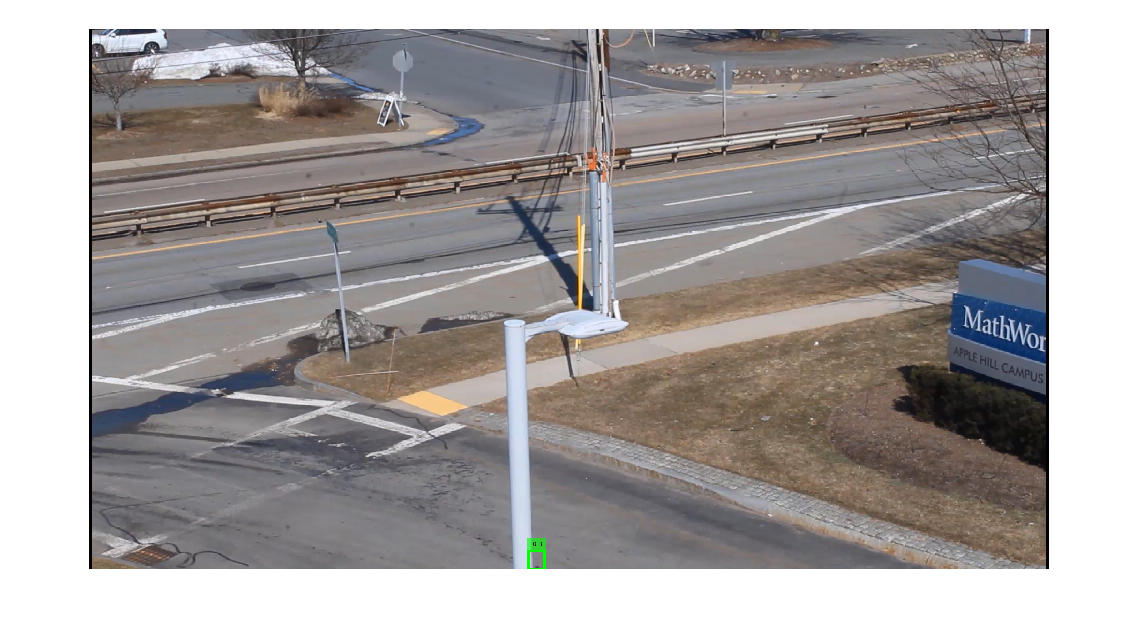

v = VideoReader("MathWorksTraffic.mp4");
vidOut = VideoWriter("CarsDetected1.mp4");
startFrame = 1;
numFrames = v.NumFrames;

% Baseline frame
of = opticalFlowFarneback;
frame = read(v,startFrame);
estimateFlow(of,im2gray(frame));

% Compare next frame to baseline to calculate optical flow
frame = read(v,startFrame + 1);
flow = estimateFlow(of,im2gray(frame));

% Remove unwanted signal from the mask
magThresh = 2.8;
mask = (flow.Magnitude > magThresh);
mask = bwareafilt(mask,[500, Inf]);
mask = imclose(mask,strel("disk",20,0));

% Apply mask to all color spaces
maskedFrame = frame;
maskedFrame(repmat(~mask,[1 1 3])) = 0;

% Get Bounding box data of the Moving Cars and apply it to the Cars present in the Frame
movObjs = regionprops("table",mask,flow.Vx,["MeanIntensity","BoundingBox","Centroid"]);
if ~isempty(movObjs)
    labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,string(round(movObjs.MeanIntensity,1)),LineWidth=5, Color="green",TextColor="black");
end
imshow(labelFrame)


open(vidOut)
writeVideo(vidOut, labelFrame)

for ii = startFrame+2:numFrames
    frame = read(v,ii);
    flow = estimateFlow(of,im2gray(frame));

    % Create the mask for pixels with high optical flow magnitude values
    mask = (flow.Magnitude > magThresh);

    % Remove unwanted signal from the mask
    mask = bwareafilt(mask,[500, Inf]);
    mask = imclose(mask,strel("disk",20,0));

    % Create magnitude labels
    movObjs = regionprops("table",mask,flow.Vx,"MeanIntensity","BoundingBox");

    % Check that there has been a detection
    if ~isempty(movObjs)
        labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,string(round(movObjs.MeanIntensity,1)),LineWidth=5, Color="green",TextColor="black");
    end

    % Write new masked frame to video reader
    writeVideo(vidOut,labelFrame)
end

close(vidOut)